# Visualizing the number of blocks in a Simulink model?

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_03_14_SimulinkSankey/SimulinkSankey.prj)

I was recently discussing different ways to visualize the content of a Simulink model with colleagues. Working in technical support, I receive models from users every day and it's always useful to quickly get a feeling of "*what's in that model?*". 

At some point during the discussion, my colleague [Reid Spence](https://www.mathworks.com/matlabcentral/profile/authors/12935569) said "*This would probably be useful to visualize the number of blocks in different subsystems using something like a *[*Sankey diagram*](https://en.wikipedia.org/wiki/Sankey_diagram)".

I thought that idea had potential, so I decided to give it a try.

## Chart Examples

When I need a fancy type of visualization that does not ship with MATLAB, I usually begin my search with [MATLAB File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/). In this case, my search led me to [Chart Examples](https://www.mathworks.com/matlabcentral/fileexchange/65857-chart-examples) by my colleague [Ken Deeley](https://www.mathworks.com/matlabcentral/profile/authors/2987674). Based on the image on File Exchange, I think this will do what I need!

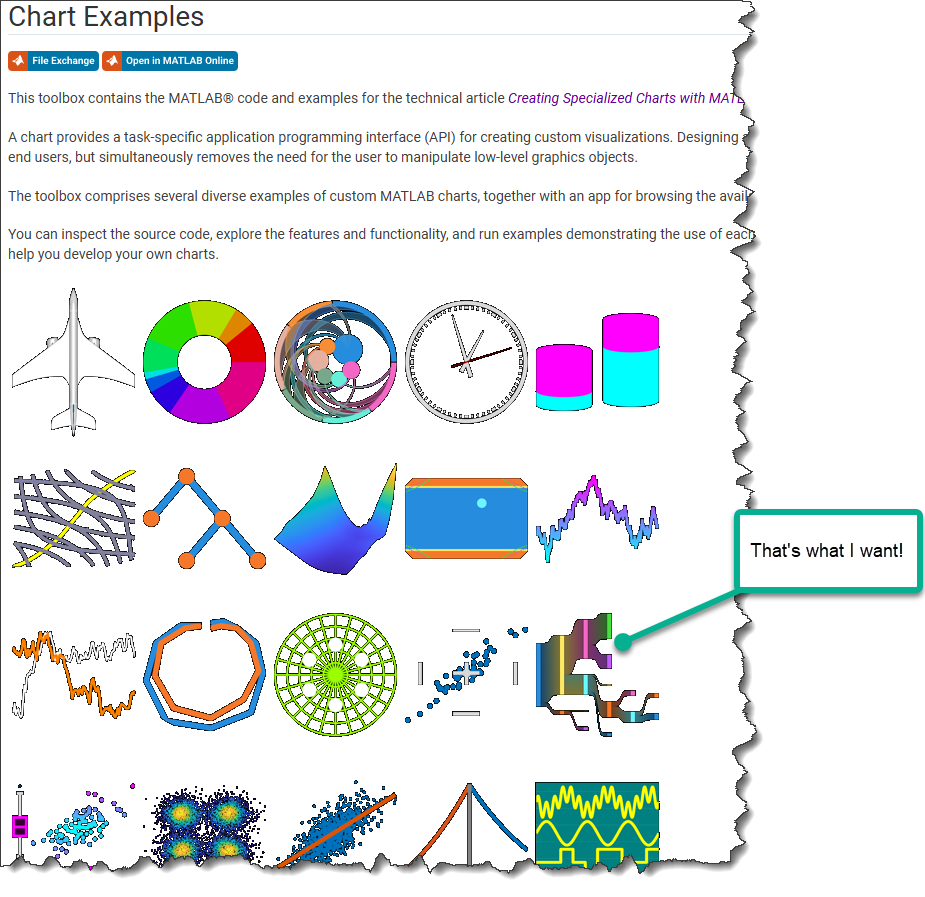

Looking at the examples included, I could quickly see that:

- The function `SankeyChart` takes a [`digraph`](https://www.mathworks.com/help/matlab/ref/digraph.html) as input

- `digraph` can take a [`table`](https://www.mathworks.com/help/matlab/ref/table.html) as input

- The table needs two variables: `EndNodes` can be a two-column string array, and `Weight`, for the weight of each node

Here is a simple example:

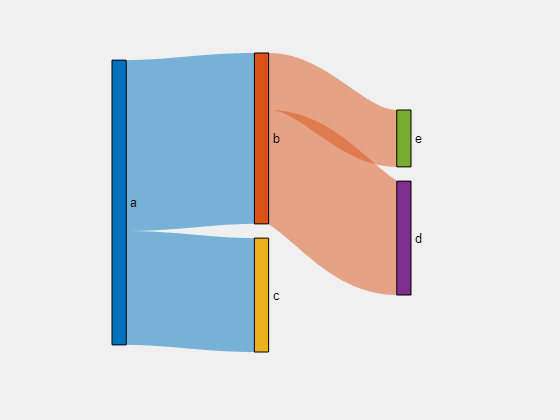

EndNodes = ["a","b";"a","c";"b","d";"b","e"];
Weight = [5 2 3 1]';
T = table(EndNodes,Weight);
D = digraph(T);
f = uifigure;
SC = SankeyChart( "Parent", f, "GraphData", D );

In some sense, it's kind of like a fully expanded Model Browser, with the additional possibility to give weights to each subsystem, corresponding to the number fo blocks they contain.

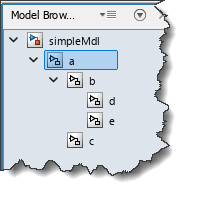

## From Model to Table

The first and most important thing I had to do is create the table. I came up with this simple recursive function:

It's probably not the most efficient implementation, especially due to the call to `Simulink.findBlocks` in the loop, but that will do the job for now.

Let's try it with one of our shipping examples: [Air Traffic Control Radar Design](https://www.mathworks.com/help/simulink/slref/air-traffic-control-radar-design.html)

openExample('simulink_aerospace/AirTrafficControlRadarDesignExample','workDir',pwd)
open_system('aero_atc');

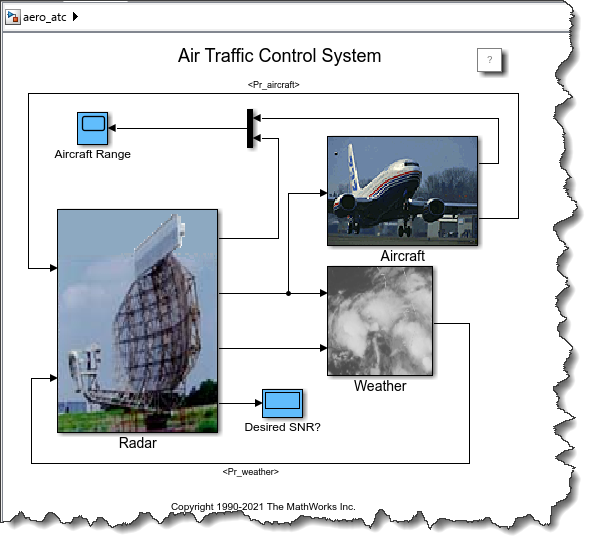

Just looking at the top level, can you guess if there are more blocks inside `Radar`, `Aircraft`, or `Weather`?

T = table();
T = mdlTable(T,'aero_atc')

T = 10×2 table
                               EndNodes                                Weight
    _______________________________________________________________    ______

    "aero_atc"          "aero_atc/Aircraft"                              10  
    "aero_atc"          "aero_atc/More Info"                              1  
    "aero_atc"          "aero_atc/Radar"                                 94  
    "aero_atc/Radar"    "aero_atc/Radar/Calculate↵SNR"                   7  
    "aero_atc/Radar"    "aero_atc/Radar/Calculate Antenna Area"          18  
    "aero_atc/Radar"    "aero_atc/Radar/Calculate Antenna Gain"           7  
    "aero_atc/Radar"    "aero_atc/Radar/Calculate Noise of Antenna"      12  
    "aero_atc/Radar"    "aero_atc/Radar/Check SNR"                        9  
    "aero_atc/Radar"    "aero_atc/Radar/Estimate Range"                  11  
    "aero_atc"          "aero_atc/Weather"                 

## From Table to Sankey

Once the table is created, I can create the `digraph` and the Sankey diagram:

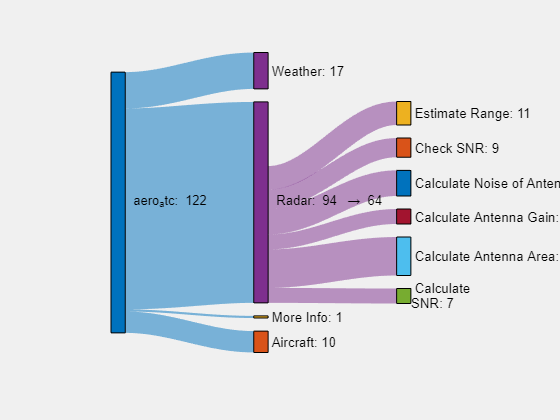

DG = digraph(T);
f = uifigure;
SC = SankeyChart( "Parent", f, "GraphData", DG );
SC.LabelIncludeTotal = "on";
SC = fixBlockNames(SC);

The last line `fixBlkNames` is a simple function I created to replace the blockpaths with the block names. Using the full blockpath easily becomes large, cluttering the diagram.

## **Larger Models**

I tried with a few larger models. This made me realize that many small subsystems with just a few blocks are often cluttering the diagram. So I decided to include a threshold and filter out those small subsystems. Here is my final function:

Here is what it looks like for example [Collision Avoidance and Trajectory Tracking of a Marine Vessel](https://www.mathworks.com/help/simulink/slref/marine-vessel-collision-avoidance-and-trajectory-tracking.html), which contains 3680 blocks, with the diagram limited to subsystems with more than 100 blocks:

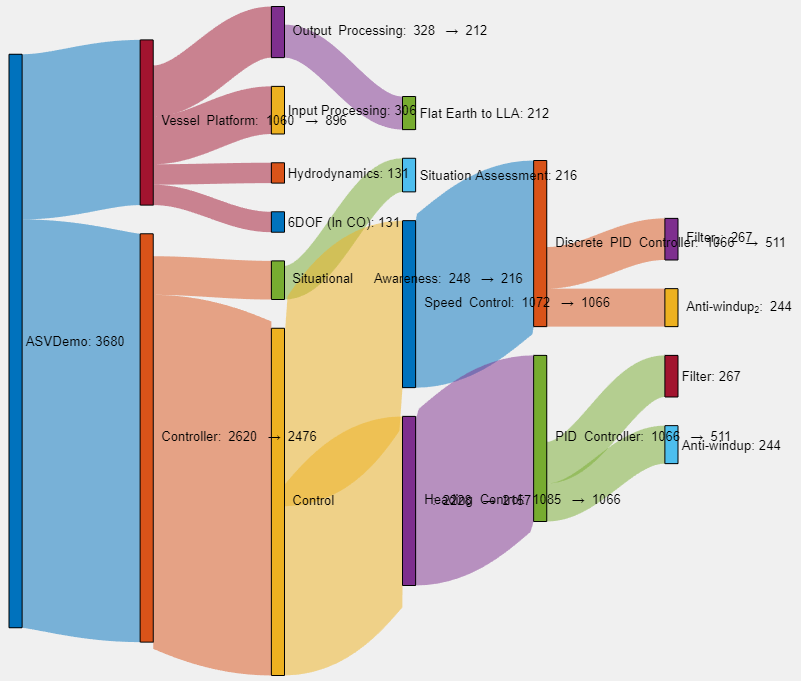

I tried pushing my luck a bit and plotted the [Double Lane Change Reference Application](https://www.mathworks.com/help/vdynblks/ug/double-lane-change-reference-application.html) from the [Vehicle Dynamics Blockset](https://www.mathworks.com/help/vdynblks/index.html), which contains 12,000 blocks. Here is the result with the limit set to 100 blocks:

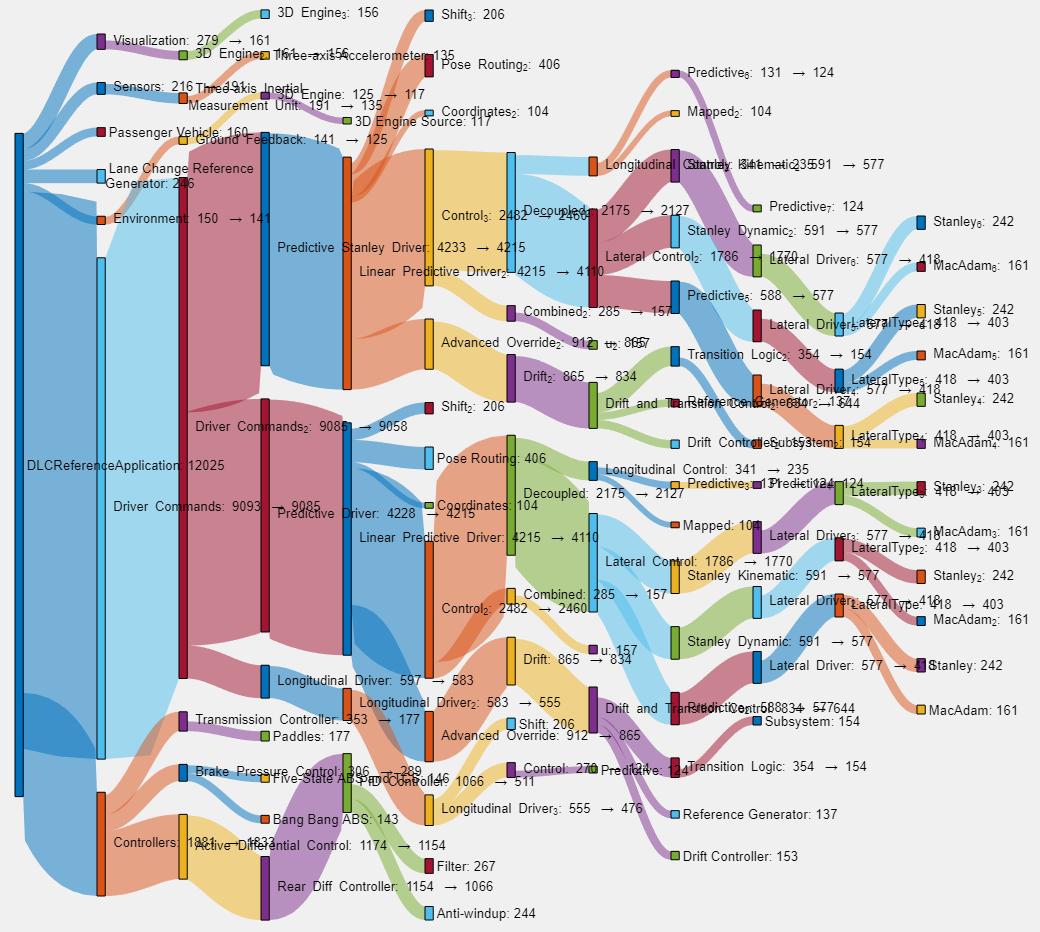

## Other Tools

While we are on that topic, here is a list of tools included with Simulink to help capturing what is inside a model: 

- [Model Maintainability Metrics](https://www.mathworks.com/help/slcheck/ref/model-maintainability-metrics.html): Included with Simulink Check, this tool helps you assess your model and other design artifacts with respect to many metrics like size, architecture, and complexity

- [Dependency Analyzer](https://www.mathworks.com/help/matlab/ref/dependencyanalyzer-app.html): An interactive tool for visualizing the files needed and impacted by a Simulink model.

- [`sldiagnostics`](https://www.mathworks.com/help/simulink/slref/sldiagnostics.html): Has a `CountBlocks` option to return the number of blocks for each `BlockType` in a model

- [`find_mdlrefs`](https://www.mathworks.com/help/simulink/slref/find_mdlrefs.html): Returns the list of model blocks in a model, and the models they reference

- [`Simulink.findBlocks`](https://www.mathworks.com/help/simulink/slref/simulink.findblocks.html) and [`Simulink.findBlocksOfType`](https://www.mathworks.com/help/simulink/slref/simulink.findblocksoftype.html): If you need to create a custom tool like I did in this post, that's probably the core API you will need to analyze what is in your model.

## Now it's your turn

The code presented here is obviously in a rough shape, I only spent an hour putting that together. If you think this is useful and worth polishing, or have suggestions for improvements, let me know in the comments below. If you try [my code](https://github.com/simulink/blog/tree/main/2025_03_14_SimulinkSankey) with your model and run into issues, also let me know in the comments below.